y(n) = -(1/6)y(n-1) + (1/18)y(n-2) + x(n)

1*y(n) + (1/6)y(n-1) - (1/18)y(n-2) = 1*x(n)

=> a0=1, a1=1/6, a2=-1/18, b0=1

b = 1

b = 1

a = [1 1/6 -1/18]

a =     1.0000    0.1667   -0.0556


[Hw, fw] = freqz(b, a)

Hw =    0.9000 + 0.0000i
   0.9000 + 0.0003i
   0.9000 + 0.0006i
   0.9000 + 0.0008i
   0.9000 + 0.0011i
   0.9000 + 0.0014i
   0.9000 + 0.0017i
   0.9000 + 0.0019i
   0.8999 + 0.0022i
   0.8999 + 0.0025i


fw =          0
    0.0061
    0.0123
    0.0184
    0.0245
    0.0307
    0.0368
    0.0430
    0.0491
    0.0552


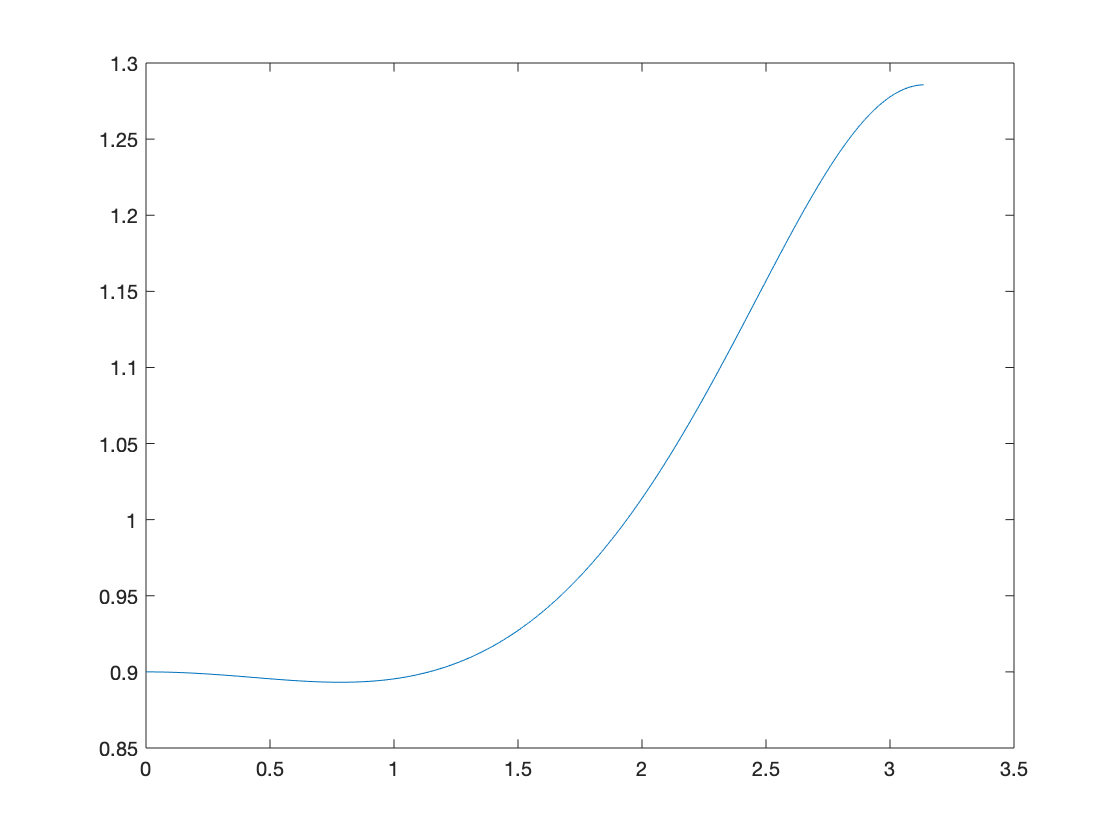

plot(fw, abs(Hw))

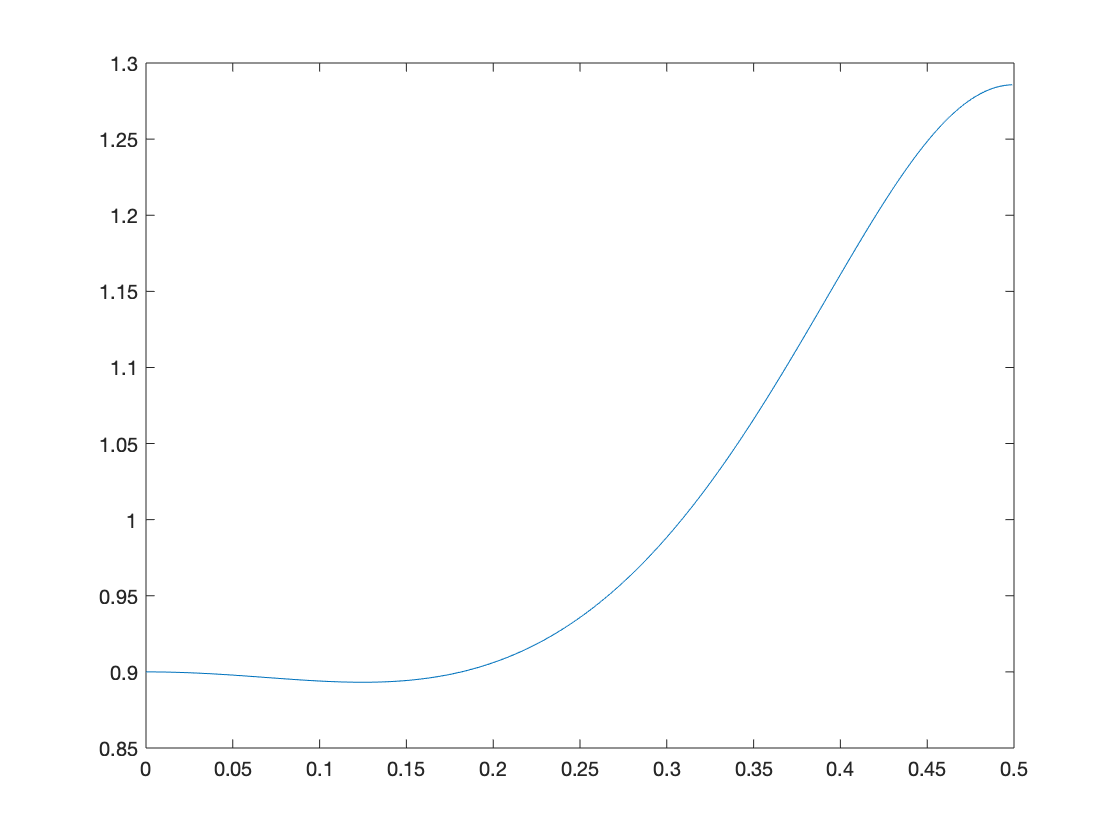

plot(fw/(2*pi), abs(Hw))

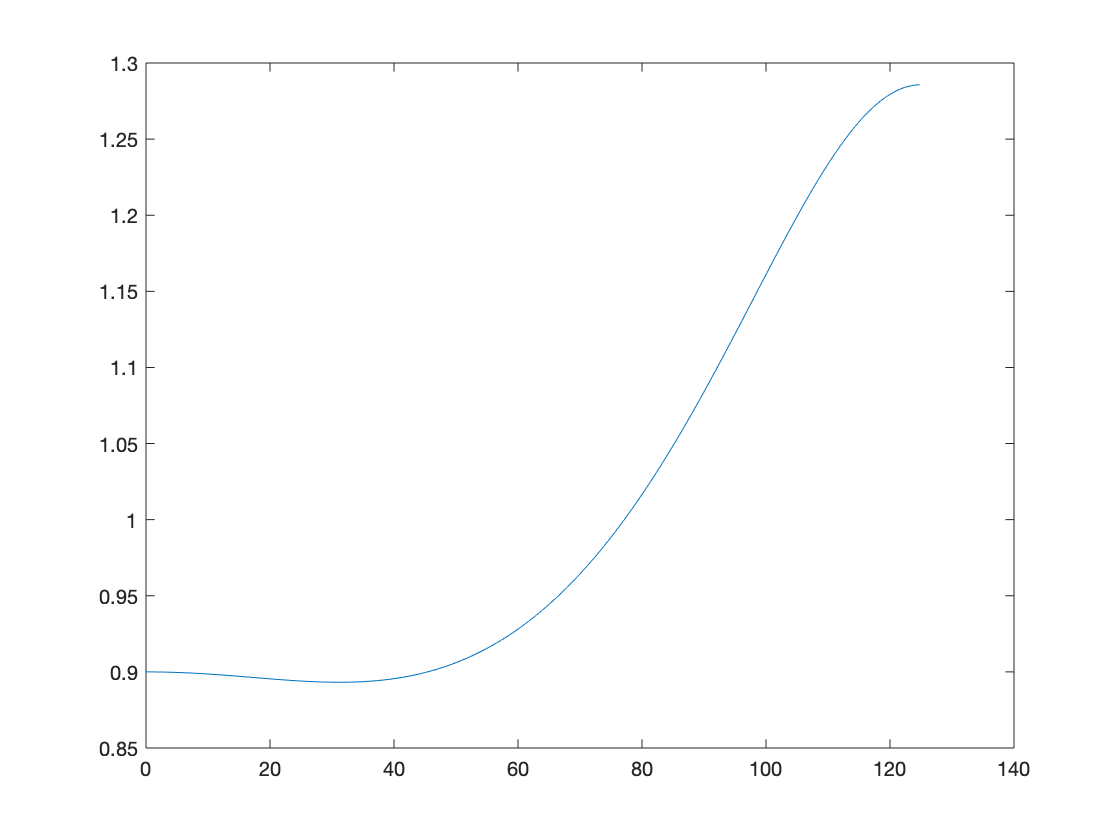

plot(fw/(2*pi)*250, abs(Hw))

Y(z) + (1/6)*Y(z)*z^(-1) - (1/18)*Y(z)*z^(-2) = X(z)

Y(z)*(1 + (1/6)*z^(-1) - (1/18)*z^(-2)) = X(z)

H(z) = Y(z)/X(z) = 1/(1 + (1/6)*z^(-1) - (1/18)*z^(-2))

H(z) = z^2/(z^2 + (1/6)*z - (1/18)) = z^2/((z+1/3)(z-1/6))